# dinteg_ofi

performs the integral double of a sampled signal with the optimally filtered integration (OFI method).

## Syntax

pos=dinteg_ofi(acc,freq)

## Description

`pos=dinteg_oci(acc,freq)` performs the integral double of a signal `acc` sampled at `freq` Hz with the the optimally filtered integration (OFI method). 

To reduce the low frequency acceleration noise the acceleration signal is high-pass-filtered, with a 2nd order Butterworth filter with an *f**c *Hz cut frequency, calculated from data of a given cycle with known equal initial and final velocities. After filtering, a first integration produced instantaneous velocity. The numerical method chosen to integrate the data is the Cavalieri–Simpson. If the so-estimated final velocity is close to the initial velocity, they are supposed as equal, and a weighted direct and reverse integration is applied, aimed to reduce the time drift in velocity. 

				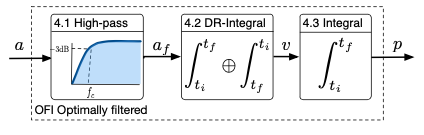

Notice that this method, contrary to the LRI and MSI methods, did not need a general assumption about the velocity at the end of the integration time 

More information: 

Köse, A.; Cereatti, A.; Della Croce, U. Bilateral step length estimation using a single inertial measurement 							unit attached to the pelvis. *J. NeuroEng. Rehabil. ***2012**, *9*, 9. 							

## Examples

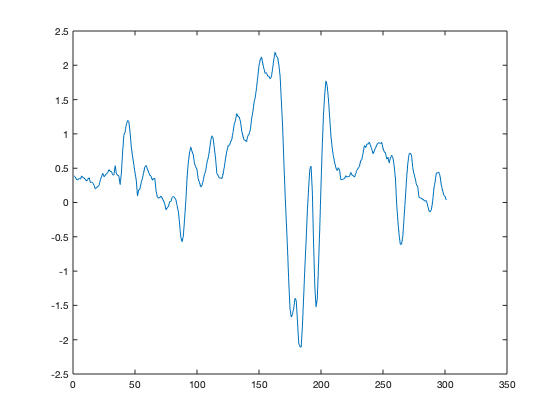

% cargamos datos de una acelerometro que sube y vuelve a la posicion de
% reposo:
filename='../simur_data/SAL.log';
datosxs=load(filename);
acc=datosxs(100:400,2)+9.8;
plot(acc);

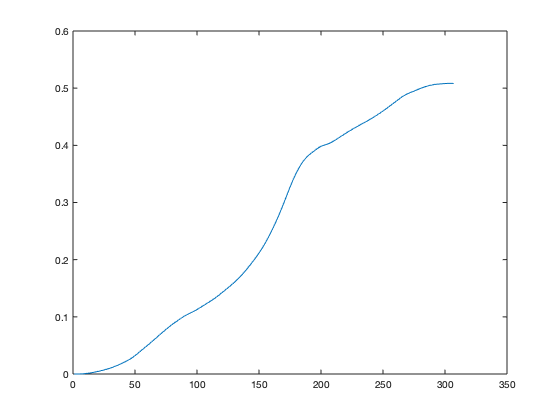

plot(dinteg_ofi(acc,100));